# MIMO Capacity Calculations

In this demo, we show how to make some simple capacity estimates for a MIMO channel.  In going through this demo, you will learn to:

- Compute the virtual directions of a narrowband MIMO channel and their SNRs

- Compute the capacity via diagonalization assuming CSI-T and CSI-R

- Perform optimal power allocation with water-filling

- Compute the capacity with linear equalizers including zero forcing and MMSE

- Compute the statistical covariance matrix and the optimal statistical pre-coder

We will address how to implement the MIMO communication blocks in a subsequent demo.

## Antenna and Channel Parameters

This file is set-up to consider two sets of parameters based on the variable, `simParam`.  You can select one of two values:

- `simParam = 'highDim'`:  High-dimensional arrays with 4x4 URA at the TX and 8x1 ULA at the RX.  The paths are angularly clustered so the channel has lower rank.  The values are what could occur in a mmWave system.

- `simParam = 'lowDim'`:  Low-dimensional arrays with 4x1 ULAs at the TX and the RX.  The paths are angularly spread out to model a rich scattering enviroment.  The values are intended to be representative of a sub-6 GHz system.

% Select either 'highDim' or 'lowDim'
simParam = 'lowDim';

if strcmp(simParam, 'highDim')
    % High-dimensional parameters
    fc = 28e9;      % frequency
    lambda = physconst('LightSpeed')/fc;
    
    % Array parameters
    dsep = 0.5*lambda;   % element spacing
    nantRx = 8;          % Number of RX elements
    nantTx = [4,4];      % Number of TX elementsa
    arrRx = phased.ULA(nantRx,dsep);
    arrTx = phased.URA(nantTx,dsep);
else
    % Low-dimensional parameters
    fc = 2.3e9;      % frequency
    lambda = physconst('LightSpeed')/fc;
    
    % Array parameters
    dsep = 0.5*lambda;   % element spacing
    nantRx = 4;          % Number of RX elements
    nantTx = 4;      % Number of TX elementsa
    arrRx = phased.ULA(nantRx,dsep);
    arrTx = phased.ULA(nantTx,dsep);
end

Just for illustration, we generate 20 paths with some distribution on the path parameters.  Feel free to try this with other parameters.

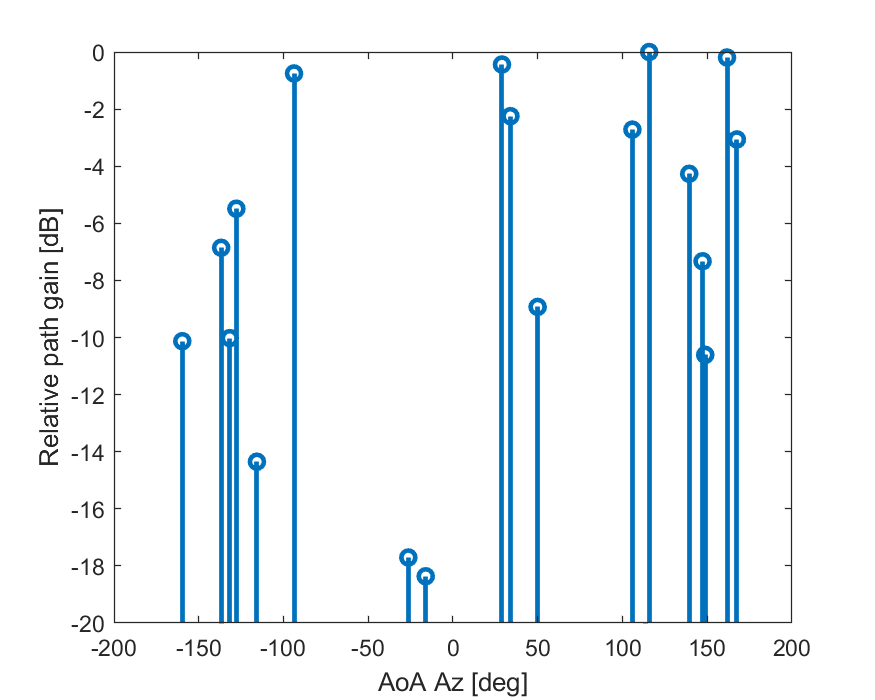

% Path clusters
npaths = 20;
gain = -exprnd(10,npaths,1);
gain = gain - max(gain);

% Generate random paths
if strcmp(simParam, 'highDim')
    % Use spatially clustered paths
    aodAz = unifrnd(-30,30,npaths,1);
    aoaAz = unifrnd(-60,60,npaths,1);
else
    % Use spatially uniform paths
    aodAz = unifrnd(-180,180,npaths,1);
    aoaAz = unifrnd(-180,180,npaths,1);
end    
aoaEl = unifrnd(-10,10,npaths,1);
aodEl = unifrnd(-10,10,npaths,1);

% Plot the paths vs. AoA
clf;
set(gcf,'Position', [0,0,500,400]);
stem(aoaAz, gain, 'Linewidth', 2, 'BaseValue', -20);
ylim([-20,0]);
xlabel('AoA Az [deg]');
ylabel('Relative path gain [dB]');

## Computing the Narrowband Channel Matrix

We first compute the channel matrix at some random frequency and time.  The time and frequency will determine the phases along the paths.  But, here we just assume we can treat them as uniform random variables.

% Random phases
phase = unifrnd(-pi,pi,npaths,1);

% Create a steering vector object
svObjRx = phased.SteeringVector('SensorArray',arrRx);
svObjTx = phased.SteeringVector('SensorArray',arrTx);
nrx = arrRx.getNumElements();
ntx = arrTx.getNumElements();

% Get the steering vectors
SvRx = svObjRx(fc, [aoaAz aoaEl]');
SvTx = svObjTx(fc, [aodAz aodEl]');

% Create channel matrix
gainComplex = db2mag(gain).*exp(1i*phase);
gainComplex = gainComplex / norm(gainComplex);
H = reshape(SvRx,nrx,1,npaths).*reshape(SvTx,1,ntx,npaths).*reshape(gainComplex,1,1,npaths);
H = sum(H, 3);

Normalize the Channel Matrix for an SNR per antenna

H = sqrt(nrx*ntx)*H / norm(H, 'fro');

## Computing the Capacity with CSI-T and CSI-R and Uniform Power Allocation

To compute the capacity, we first take the SVD of the channel

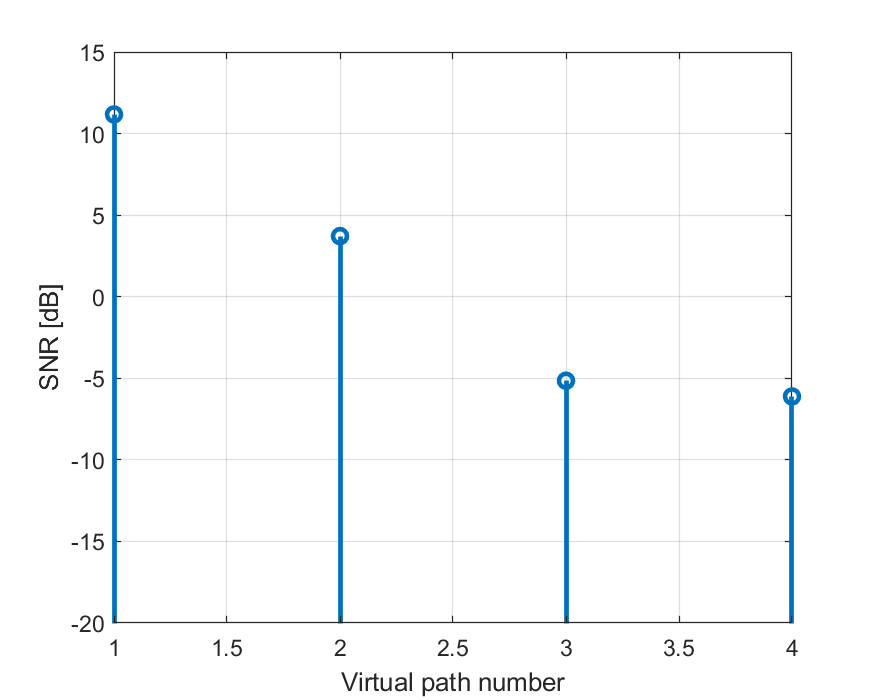

% Get the SVD
[U,S,V] = svd(H,'econ');
s = diag(S);

% Eigenvalues
lam = s.^2;

% Plot the eigenvalues.
stem(pow2db(lam), 'BaseValue', -40, 'LineWidth', 2);
xlabel('Virtual path number');
ylabel('SNR [dB]');
grid on;
if strcmp(simParam, 'highDim')
    ylim([-20, 25]);
else
    ylim([-20, 15]);
end

We now plot the rate vs. SNR with uniform power allocation across all streams.  We compare this to the capacity for a channel with the same SNR per antenna.

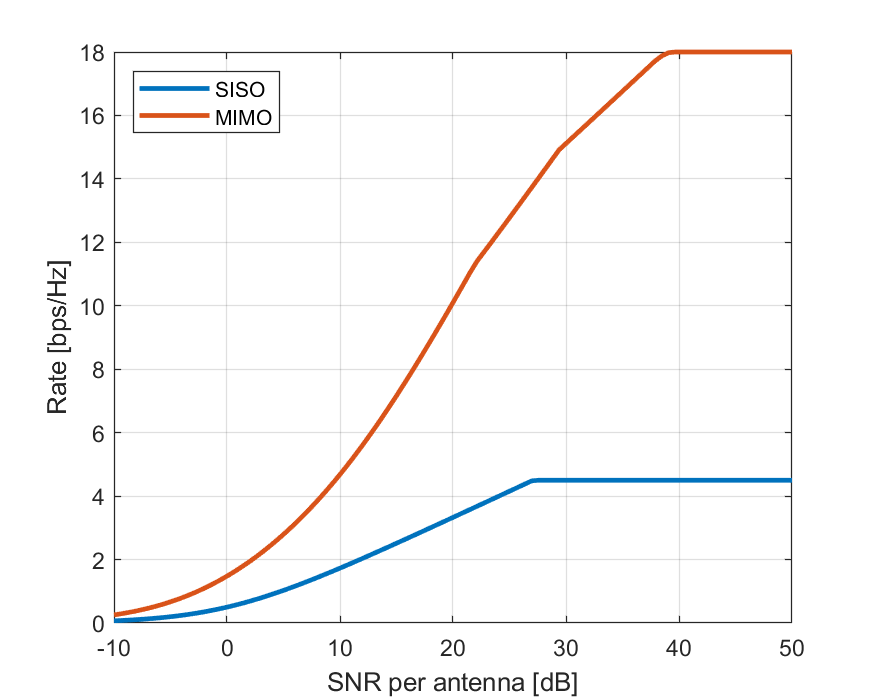

% SNR per antenna to test
snrTest = linspace(-10,50,100)';
nsnr = length(snrTest);

% Rate model parameters
bwScale = 0.5;
maxSE = 4.5;

% SISO rate
rateSISO = min(maxSE, bwScale*log2(1+ db2pow(snrTest)));

% MIMO rate with uniform power
rmax = length(s);
rateStream = min(maxSE, bwScale*log2(1+ db2pow(snrTest)*lam'/rmax));
rateMIMO = sum(rateStream, 2);

% Plot
clf;
set(gcf,'Position', [0,0,500,400]);
plot(snrTest, [rateSISO rateMIMO], 'Linewidth', 2);
grid on;
xlabel('SNR per antenna [dB]');
ylabel('Rate [bps/Hz]');
legend('SISO', 'MIMO', 'Location', 'Northwest');

We next compute the rate with beamforming.

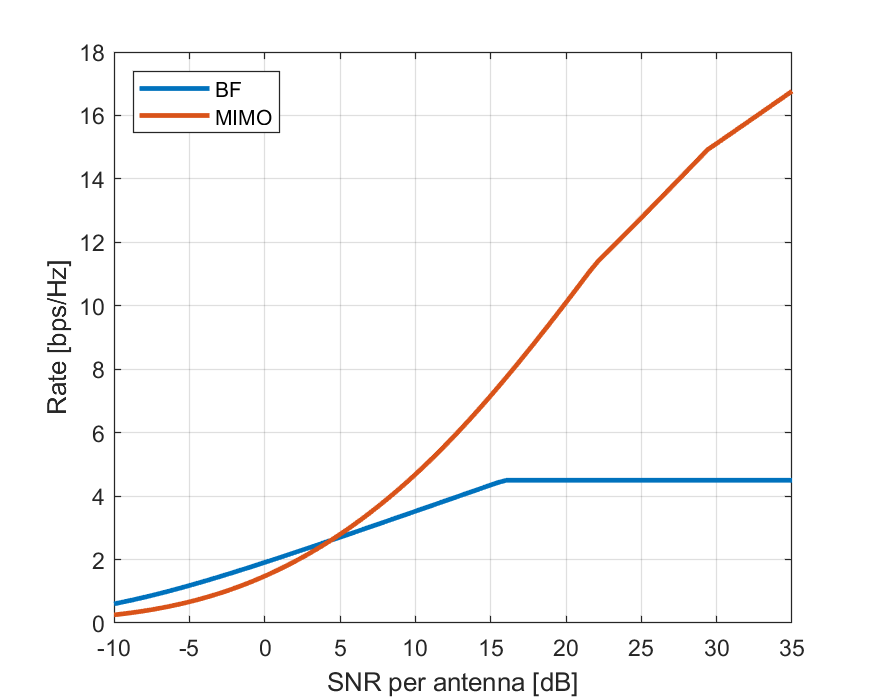

% BF rate with power allocated to top virtual path
rateBF = min(maxSE, bwScale*log2(1+ db2pow(snrTest)*lam(1)));

% Plot
clf;
set(gcf,'Position', [0,0,500,400]);
plot(snrTest, [rateBF rateMIMO], 'Linewidth', 2);
grid on;
xlabel('SNR per antenna [dB]');
ylabel('Rate [bps/Hz]');
legend('BF', 'MIMO', 'Location', 'Northwest');
xlim([-10, 35]);

## Optimizing the Power Allocation

We next optimizing the power allocation.  As an  approximation, we consider allocations where uniformly allocated power uniformly across `r` streams.  Beamforming corresponds to `r=`1.  We call this the rank selection optimization.

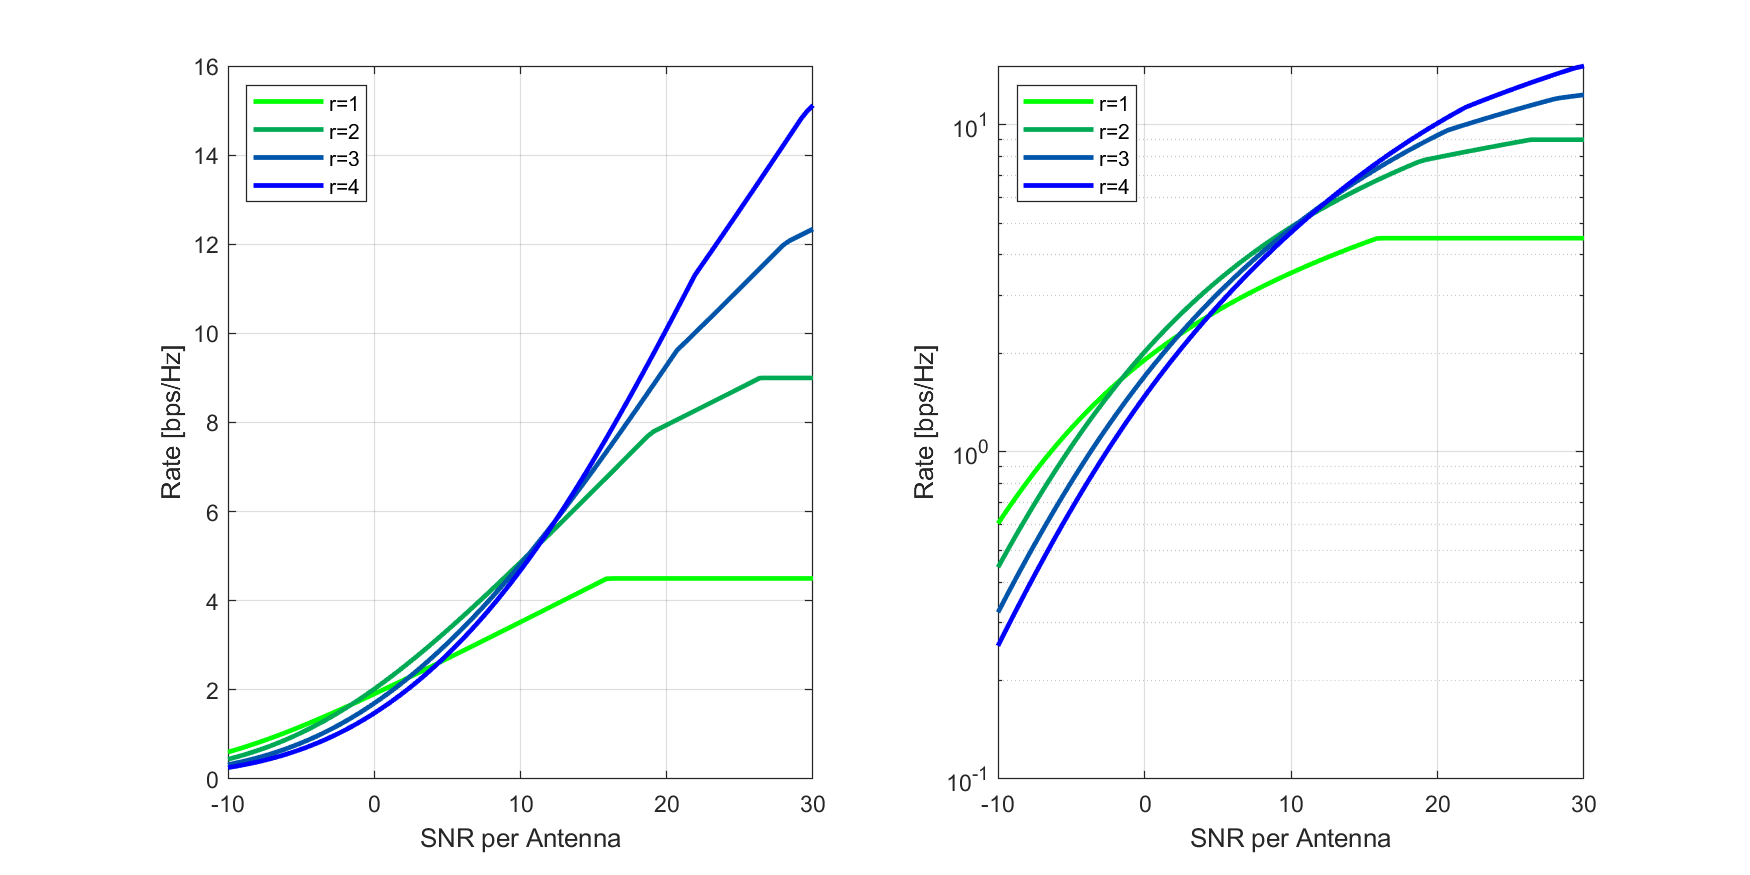

% SNRs to test
snrTest = linspace(-10,30,100)';
nsnr = length(snrTest);
rate = zeros(nsnr, rmax);

% Rate model parameters
bwScale = 0.5;
maxSE = 4.5;

for i = 1:nsnr
    for j = 1:rmax
        
        % Scale the SNR
        sscale = lam(1:j) * db2pow(snrTest(i)) / j;
        
        % Compute the rate per stream
        rateStream = min(bwScale*log2(1 + sscale), maxSE);
        
        % Compute the total rate
        rate(i,j) = sum(rateStream);
    end
    
end

clf;
set(gcf,'Position', [0,0,1000,500]);
nplot = 2;
for k = 1:nplot
    subplot(1,2,k);
    legStr = cell(rmax,1);
    for i = 1:rmax
        t = (i-1)/(rmax-1);
        col = [0, 1-t, t];
        if k==1
            plot(snrTest,rate(:,i), 'Linewidth', 2, 'Color', col);
        else
            semilogy(snrTest,rate(:,i), 'Linewidth', 2, 'Color', col);
        end
        hold on;
        legStr{i} = sprintf('r=%d', i);
    end
    hold off;
    grid on;
    xlabel('SNR per Antenna');
    ylabel('Rate [bps/Hz]');
    legend(legStr, 'Location', 'NorthWest');
end

We can now optimize the rank.

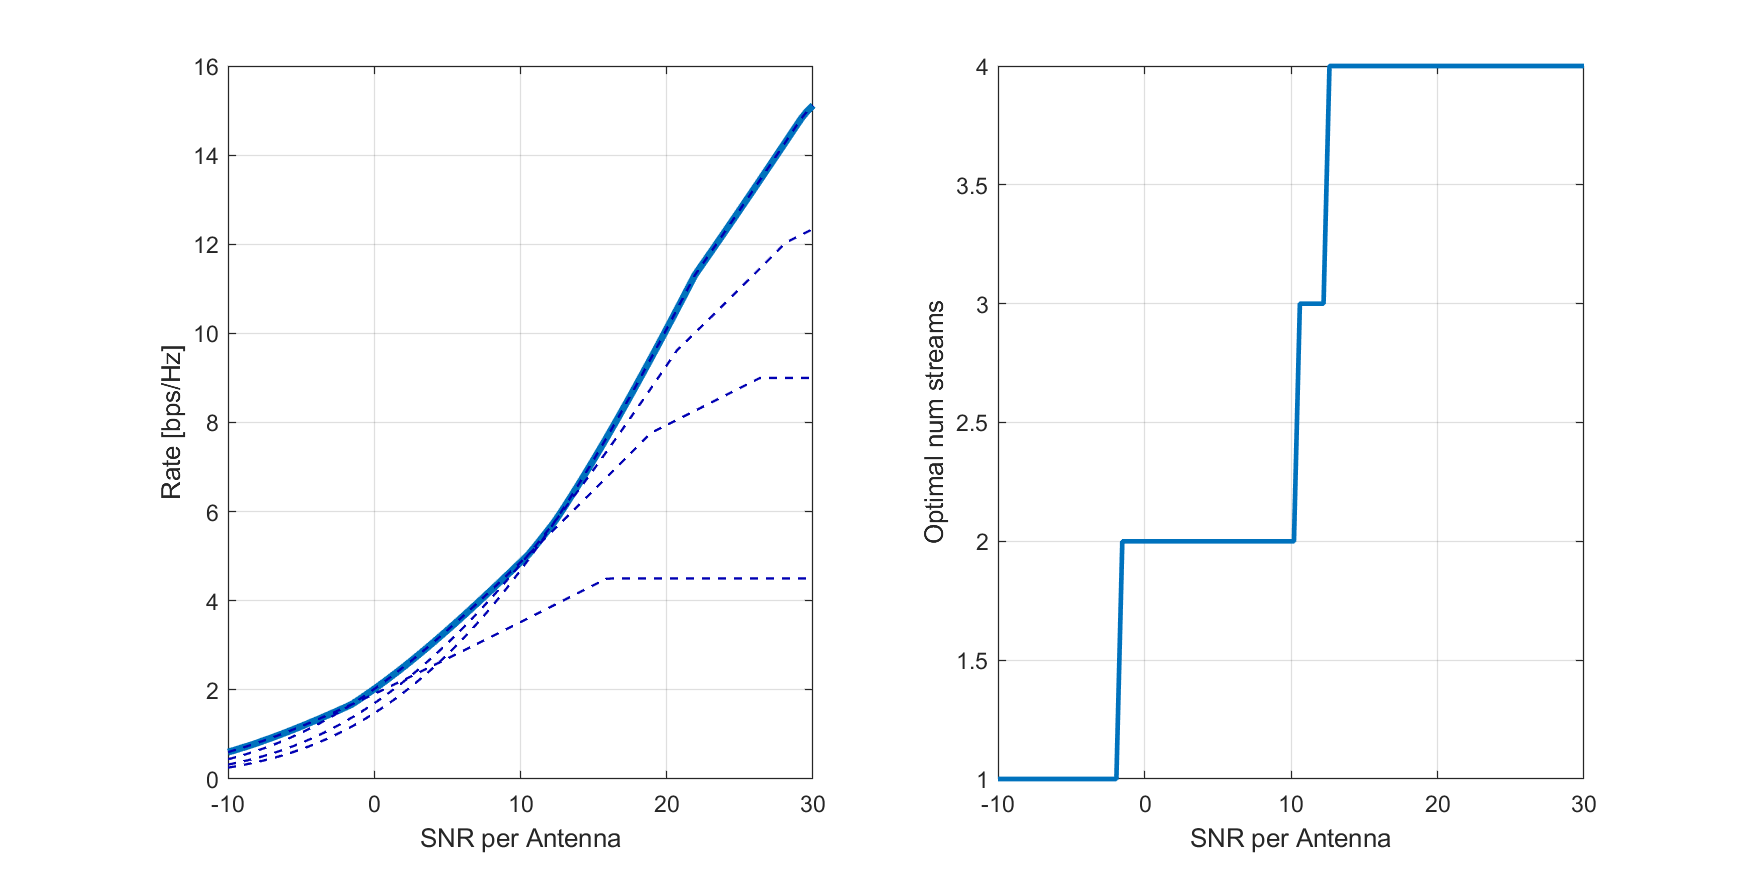

[rateRankSel, rankRankSel] = max(rate, [], 2);

subplot(1,2,1);
plot(snrTest, rateRankSel, 'Linewidth', 3);
hold on;
plot(snrTest, rate, '--', 'Linewidth', 1, 'Color', [0,0,0.7]);
hold off;

xlabel('SNR per Antenna');
ylabel('Rate [bps/Hz]');
grid on;

subplot(1,2,2);
plot(snrTest, rankRankSel, 'Linewidth', 2);
grid on;
xlabel('SNR per Antenna');
ylabel('Optimal num streams');

A more sophisticated method is use waterfilling.  I have included a simple class that performs the waterfilling using dual line search.

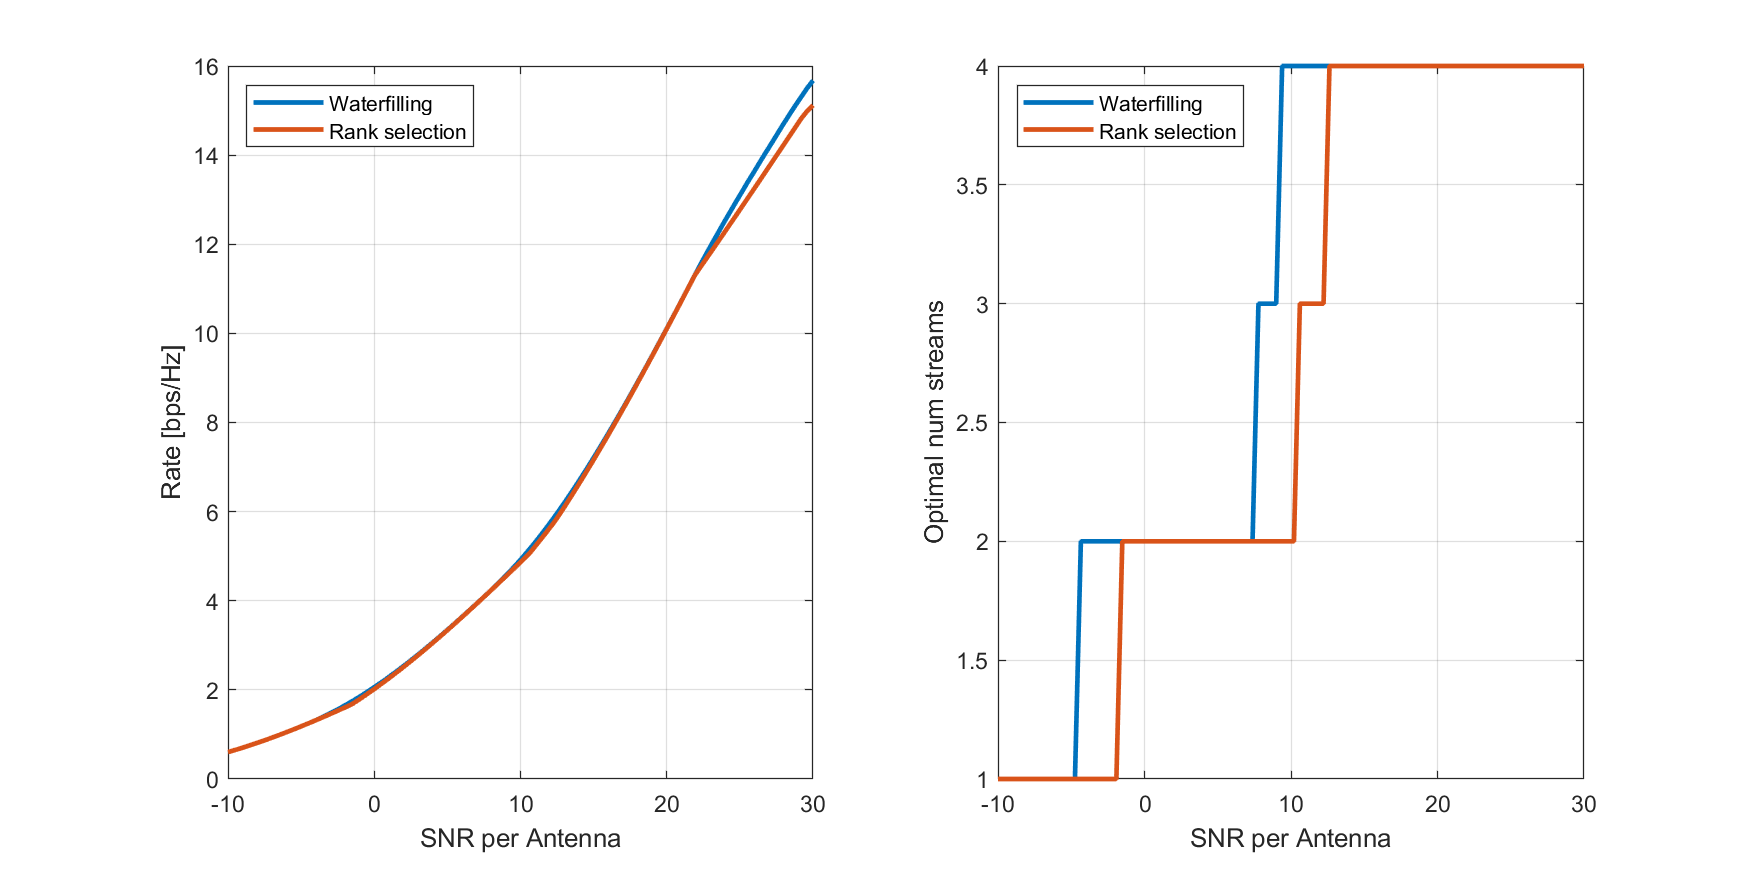

% Rate model parameters
bwScale = 0.5;
maxSE = 4.5;

% Create a water-filling object
wf = WaterFill('bwScale', bwScale, 'maxSE', maxSE);

% Rate
rateWF = zeros(nsnr,1);
rankWF = zeros(nsnr,1);

for i = 1:nsnr
    
    % Scale the SNR
    gamma = lam * db2pow(snrTest(i));
    
    [xopt, rateOpti] = wf.optimize(gamma);
    rateWF(i) = rateOpti;
    rankWF(i) = sum(xopt > 0);
    
end

clf;
set(gcf,'Position', [0,0,1000,500]);
subplot(1,2,1);
plot(snrTest,[rateWF rateRankSel], 'Linewidth', 2);
xlabel('SNR per Antenna');
ylabel('Rate [bps/Hz]');
grid on;
legend('Waterfilling', 'Rank selection', 'Location', 'Northwest');

subplot(1,2,2);
plot(snrTest, [rankWF rankRankSel ], 'Linewidth', 2);
grid on;
xlabel('SNR per Antenna');
ylabel('Optimal num streams');
legend('Waterfilling', 'Rank selection', 'Location', 'Northwest');

## TX Power Mis-Allocation Loss Without CSI-T 

When the TX has no CSI-T, there is a loss since it mis-allocates the power to virtual directions with no SNR.  We can compute this loss easily as follows.  

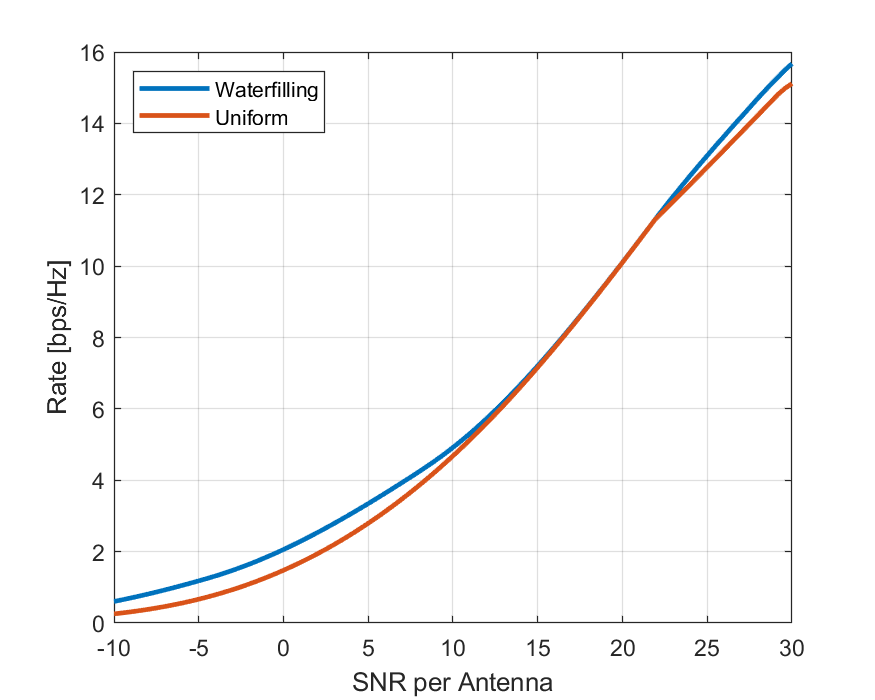


% SNR for each stream
sscale = db2pow(snrTest)*lam' / ntx;

% Compute the rate per stream
rateUniform = sum(min(bwScale*log2(1 + sscale), maxSE), 2);

clf;
set(gcf,'Position', [0,0,500,400]);
plot(snrTest, [rateWF rateUniform], 'Linewidth', 2);
grid on;
xlabel('SNR per Antenna');
ylabel('Rate [bps/Hz]');
legend( 'Waterfilling', 'Uniform', 'location', 'NorthWest');

## Performance with Linear Equalization

The capacity calculations above assumed ideal joint decoding.  We now consider the performance with simple linear equalization.  

First, for linear decoding, we need to limit the number of TX streams to be less than the channel rank.  We also do not want to TX in eigenvalues that are very small.  As a simple method to avoid this, we will select the rank, `r, `equal to the number of eigenvalues within 30 dB of the maximum eigenvalue.

% Get number of streams
nstr = sum(lam > max(lam)*1e-3);


We will then just transmit with a random pre-coder mapping `r` streams to `ntx` TX antennas.  Obviously, this is not optimal.  We will see below how to select a better pre-coder.  We can generate the random pre-coder by taking the SVD of a Gaussian iid matrix.

nstr = nrx;
if nstr < ntx
    % Generate a random unitary matrix
    X = randn(ntx,ntx) +1i*randn(ntx,ntx);
    [F,~,~] = svd(X);
    F = F(:,1:nstr);
    
    % Compute the pre-coded H matrix
    G = H*F;
else
    G = H;
end

We can now estimate the rate with linear decoding.

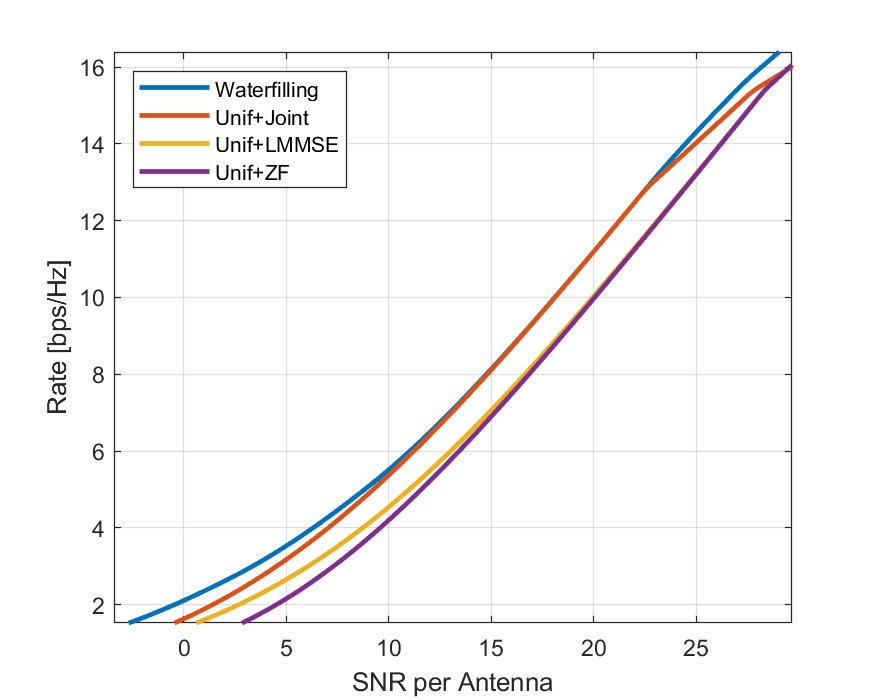

% SNR values to test
snrTest = linspace(-10,30,100);
nsnr = length(snrTest);

% Vectors to stores the rate values
rateJoint = zeros(nsnr,1);
rateLMMSE = zeros(nsnr,1);
rateZF = zeros(nsnr,1);

% Compute the eigenvalues of the pre-coded matrix
Gsq = (G')*G;
lam = max(0, real(eig(Gsq)));

% Compute ZF SINR
Qzf = inv(Gsq);

% Unscaled SNR with ZF
snrZF0 = 1./diag(Qzf);

% Loop over SNRs
for i = 1:nsnr
    
    alpha = db2pow(snrTest(i))/ntx;
    
    % Compute the rate on each stream with optimal decoding
    sinrJoint = alpha*lam;
    rateStream = min(bwScale*log2(1 + sinrJoint), maxSE);
    rateJoint(i) = sum(rateStream);
    
    % Compute the rate with ZF
    snrZF = snrZF0*alpha;
    rateStream = min(bwScale*log2(1 + snrZF), maxSE);
    rateZF(i) = sum(rateStream);
        
    % Compute the rate with LMMSE deccoding
    Q = inv(eye(nstr) + alpha*Gsq);
    Q = (Q + Q')/2;
    sinrLMMSE = max(real(1./diag(Q)-1), 0);
    rateStream = min(bwScale*log2(1 + sinrLMMSE), maxSE);
    rateLMMSE(i) = sum(rateStream);          
end
    
plot(snrTest, [rateWF rateJoint rateLMMSE rateZF], 'Linewidth', 2);
grid on;
xlabel('SNR per Antenna');
ylabel('Rate [bps/Hz]');
if nstr == ntx
    legend('Waterfilling', 'Unif+Joint', 'Unif+LMMSE', 'Unif+ZF', 'location', 'NorthWest');
else
    legend('Waterfilling', 'Pre-code + Joint', 'Pre-code + LMMSE', ...
        'Pre-code + ZF', 'location', 'NorthWest');
end

## Statistical Pre-Coding

Obtaining instantaneous CSI-T is often difficult since the channel varies in time or frequency due to small scale fading.  An option to obtain partial CSI-T is called *statistical pre-coding* where the TX learns the TX spatial covariance matrix.  This matrix is an average of `H'*H` over many fading realizations and only depends on the large scale channel parameters that vary much slower.    We first compute the TX and RX spatial covariance matrices as follows.

% Get the TX spatial covariance matrix
Qtx = reshape(SvTx,ntx,1,npaths).*reshape(conj(SvTx),1,ntx,npaths) ...
    .*reshape(abs(gainComplex).^2,1,1,npaths);
Qtx = nrx*sum(Qtx, 3);

We can get the eigenvectors in the TX directions from the TX spatial covariance matrix.

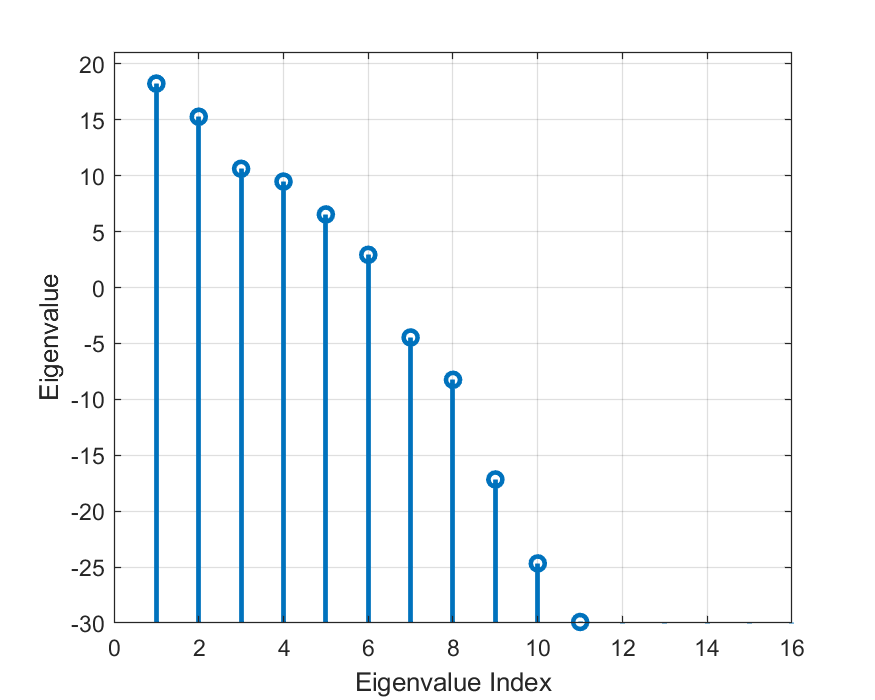


% Get the eigenvalues
[V,lam] = eig(Qtx);
lam = real(diag(lam));

% Sort the eignvalues
[lam,I] = sort(lam, 'descend');
Vstat = V(:,I);

% Plot the eigenvalues
stem(pow2db(lam), 'LineWidth', 2, 'Basevalue', -30);
xlabel('Eigenvalue Index');
ylabel('Eigenvalue');

ylim([-30, pow2db(nrx*ntx)]);
grid on;

We now estimate the rate with instantaneous and statistical pre-coding by taking a number of independent channel realizations.

nsamp = 100;  % Number of random samples
r = 4;        % TX rank

% Random phases on each path
phase = unifrnd(0,2*pi,nsamp,npaths);

% Eigenvalues for the pre-coded system with 
% instanteous and statistical pre-coding
LamInst = zeros(nsamp,r);
LamStat = zeros(nsamp,r);

for i = 1:nsamp
    
    % Generate complex gains in this sample
    g = gainComplex.*exp(1i*phase(i,:).');
    
    % Get the instantaneous H
    H = reshape(SvRx,nrx,1,npaths).*reshape(SvTx,1,ntx,npaths).*reshape(g,1,1,npaths);
    H = sum(H, 3);
    
    % Compute the instaneous eigenvalues
    s = svd(H, 'econ');
    LamInst(i,:) = s(1:r).^2;
    
    % Compute the statistically pre-coded system
    G = H*Vstat(:,1:r);
    
    % Compute the eigenvalues with statistical pre-coding
    s = svd(G, 'econ');
    LamStat(i,:) = s(1:r).^2;     
    
end

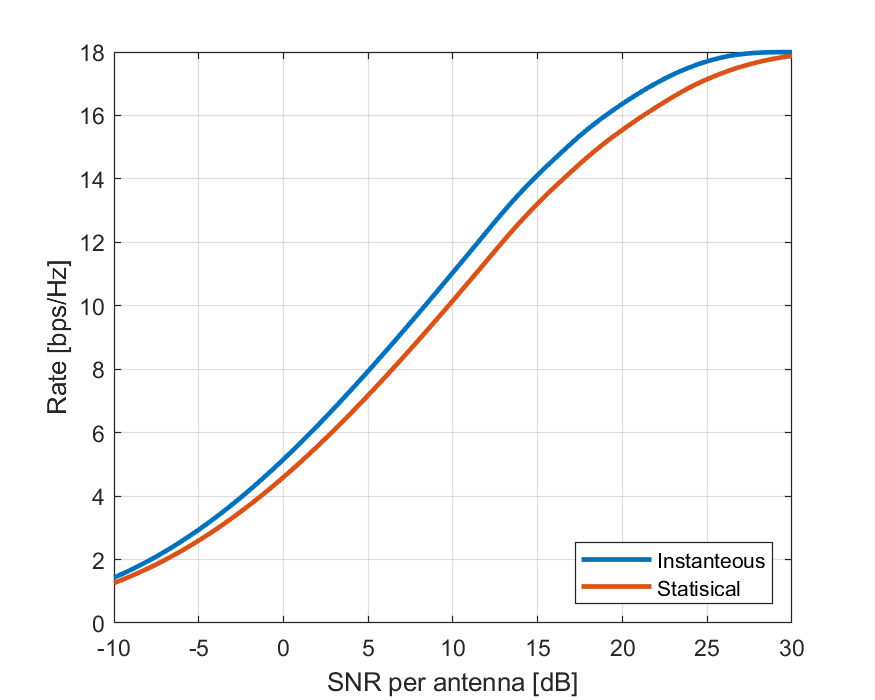

snrTest = linspace(-10,30,100)';
nsnr = length(snrTest);

rateInst = zeros(nsnr,1);
rateStat = zeros(nsnr,1);
for i = 1:nsnr
    
    snr = snrTest(i);
    
    % Get the rate with instantaneous pre-coding
    rate = sum(min(bwScale*log2(1 + db2pow(snr)*LamInst/r), maxSE), 2);
    rateInst(i) = mean(rate);
    
    % Get the rate with statistical pre-coding
    rate = sum(min(bwScale*log2(1 + db2pow(snr)*LamStat/r), maxSE), 2);
    rateStat(i) = mean(rate);    
end

plot(snrTest, [rateInst rateStat], 'Linewidth', 2);
grid on;
legend('Instanteous', 'Statisical', 'location', 'southeast');
xlabel('SNR per antenna [dB]');
ylabel('Rate [bps/Hz]');